# Review of State-Variables and MATLAB

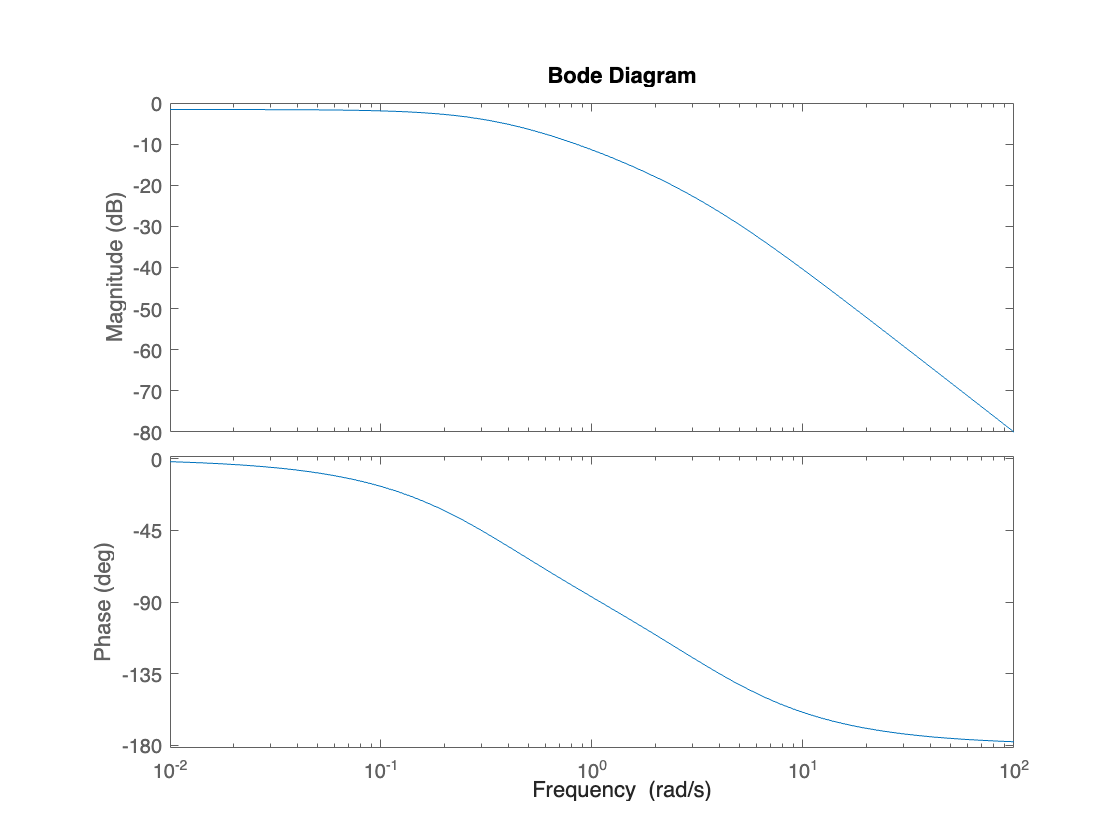


A_Plant = [0, 1; -1.2, -3.71]; % Process Matrix
B_Plant = [0; 1]; % Input Matrix
C_Plant = [1, 0]; % Output Matrix
C_Plant_full = [1, 0;
                0, 1]; % Output Matrix
D_Plant =  0;
sys_forwards = ss(A_Plant, B_Plant, C_Plant, D_Plant);
bode(sys_forwards) % open loop bode plot

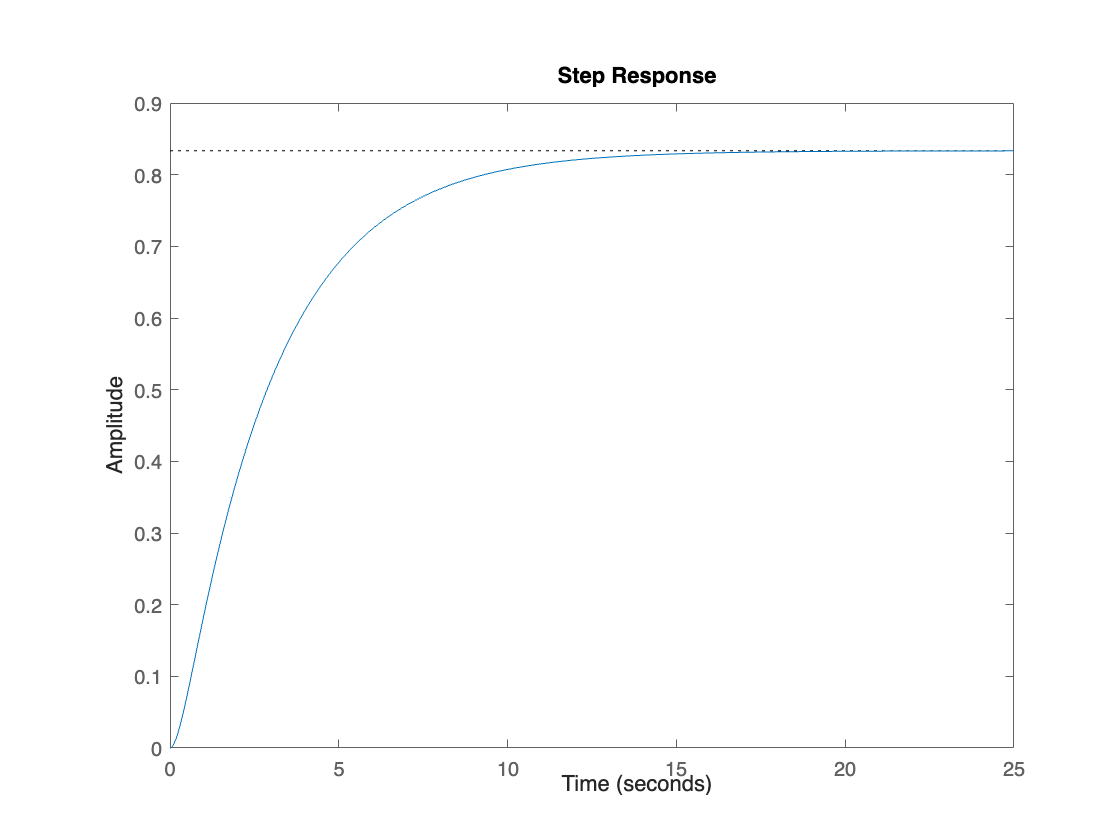

step(sys_forwards)

poles= eig(sys_forwards)

poles =    -0.3580
   -3.3520


DC_gain = dcgain(sys_forwards);
disp("DC gain:")

DC gain:


disp(DC_gain)

    0.8333



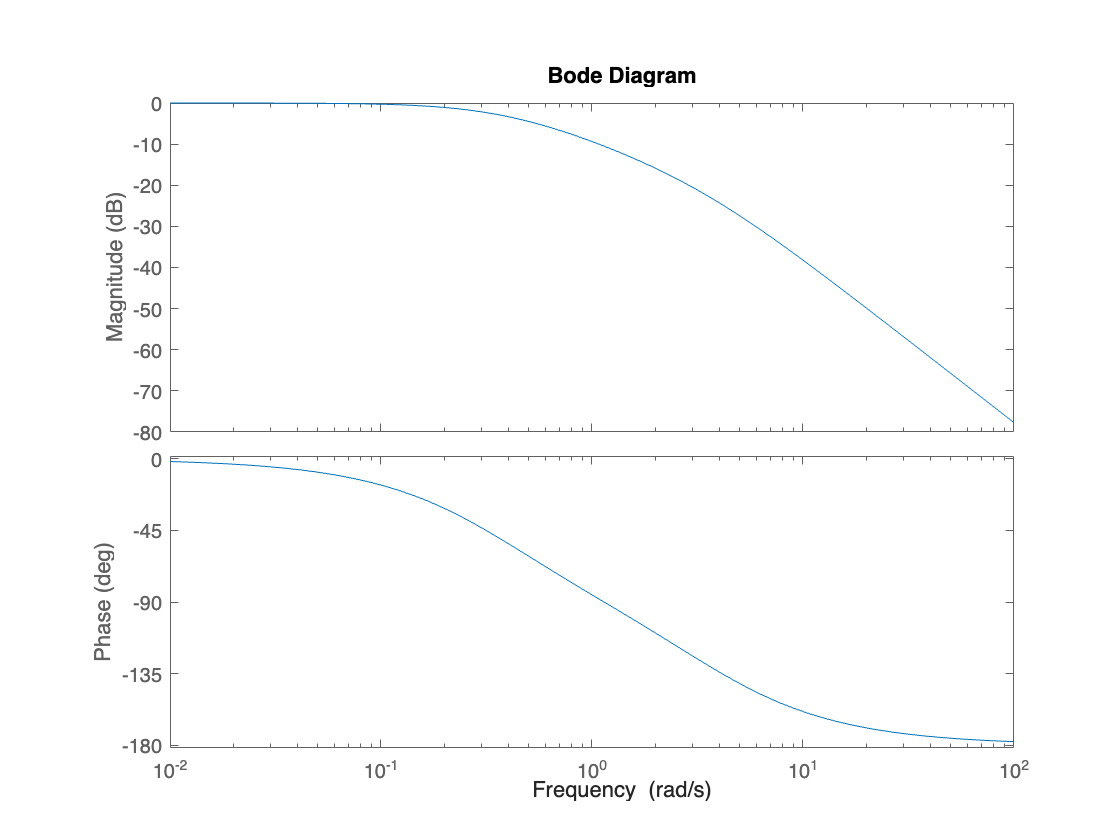

sys_forwards = ss(A_Plant, B_Plant, C_Plant_full, D_Plant);
sys_backwards = ss(0, [0, 0], 0, [0.1, 0.1]);
sys_feedback = feedback(sys_forwards, sys_backwards, -1);
sys_feedback = ss(sys_feedback.A, sys_feedback.B, [1,0,0], 0);
DC_fb_gain = 1/dcgain(sys_feedback);
sys_feedback = DC_fb_gain*sys_feedback;
bode(sys_feedback)

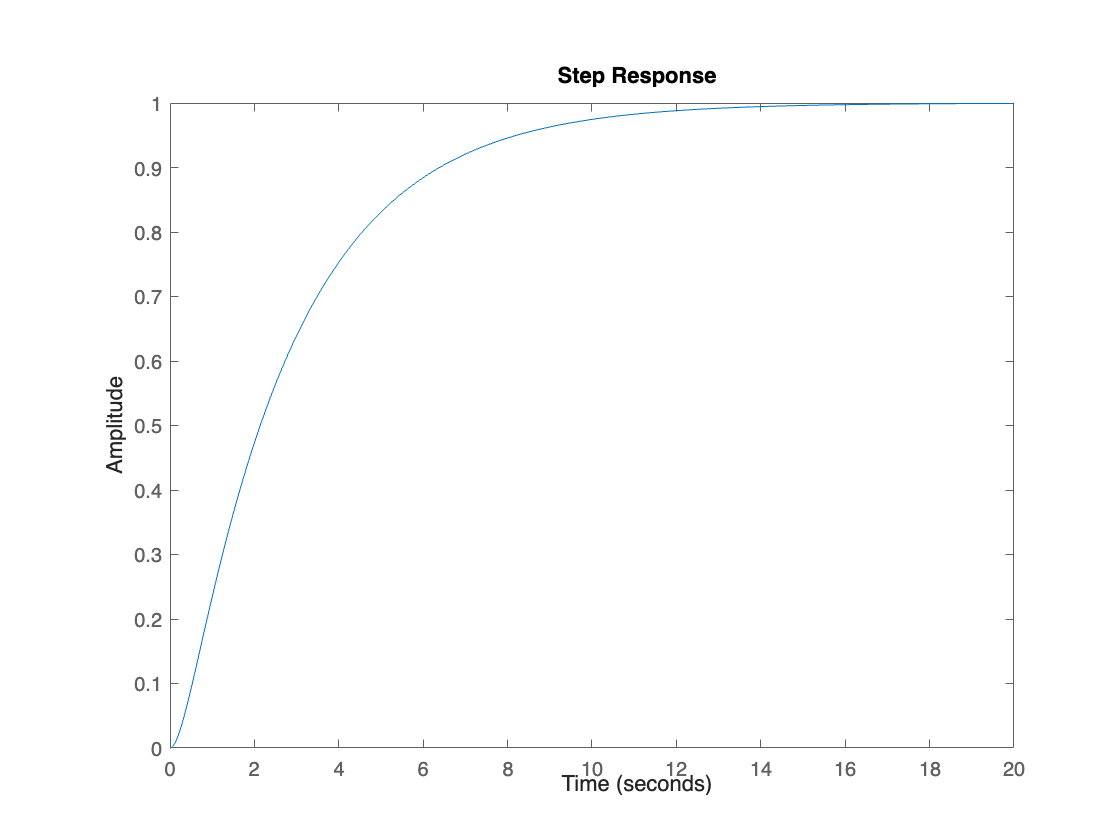

step(sys_feedback)

## Double check the result

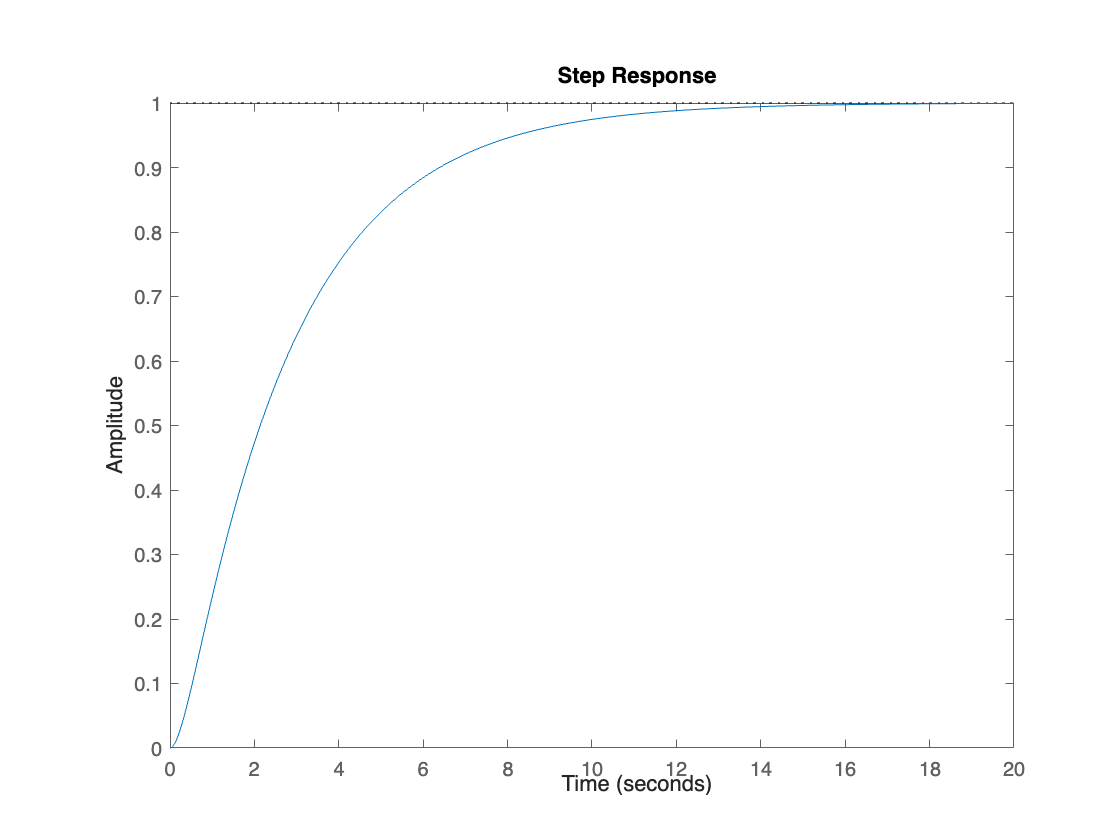

K = [0.1, 0.1];
sys_fb_check = ss(A_Plant - B_Plant*K, [0; 1], C_Plant, D_Plant);
DC_fb_gain = 1/dcgain(sys_fb_check);
sys_fb_check = DC_fb_gain*sys_fb_check;
step(sys_fb_check)

bode(sys_fb_check)

[A1,B1,C1,D1] = tf2ss([2 5 1],[1 2 3])

A1 =     -2    -3
     1     0


B1 =      1
     0


C1 =      1    -5


D1 = 2

[A,B,C,D] = tf2ss([5, 10], [1, 10])

A = -10

B = 1

C = -40

D = 5

syms s
sgm = 0.8;
wn = 4.0188;
eqn3 = s^2 + 2*sgm*wn*s + wn^2 == 0;
S = solve(eqn3)

$$S = \left(\begin{array}{c} -\frac{10047}{3125}-\frac{\sqrt{15982147084160905692771}\,\mathrm{i}}{52428800000}\\ -\frac{10047}{3125}+\frac{\sqrt{15982147084160905692771}\,\mathrm{i}}{52428800000} \end{array}\right)$$

double(S)

ans =   -3.2150 - 2.4113i
  -3.2150 + 2.4113i


## Ackerman formula calculation

F = [0, 1; -1.2, -3.71]; % Process Matrix
G = [0; 1]; % Input Matrix
H = [1, 0]; % Output Matrix
syms s
poly = expand((s+3.215+2.4113i)*(s+3.215-2.4113i))

$$poly = s^{2}+\frac{643\,s}{100}+\frac{1615059269}{100000000}$$

Sigma = [G F*G];
Alpha_F = F^2 + 6.43*F + 1615059269/100000000*eye(2)

Alpha_F =    14.9506    2.7200
   -3.2640    4.8594


K = [0 1]*inv(Sigma)*Alpha_F

K =    14.9506    2.7200


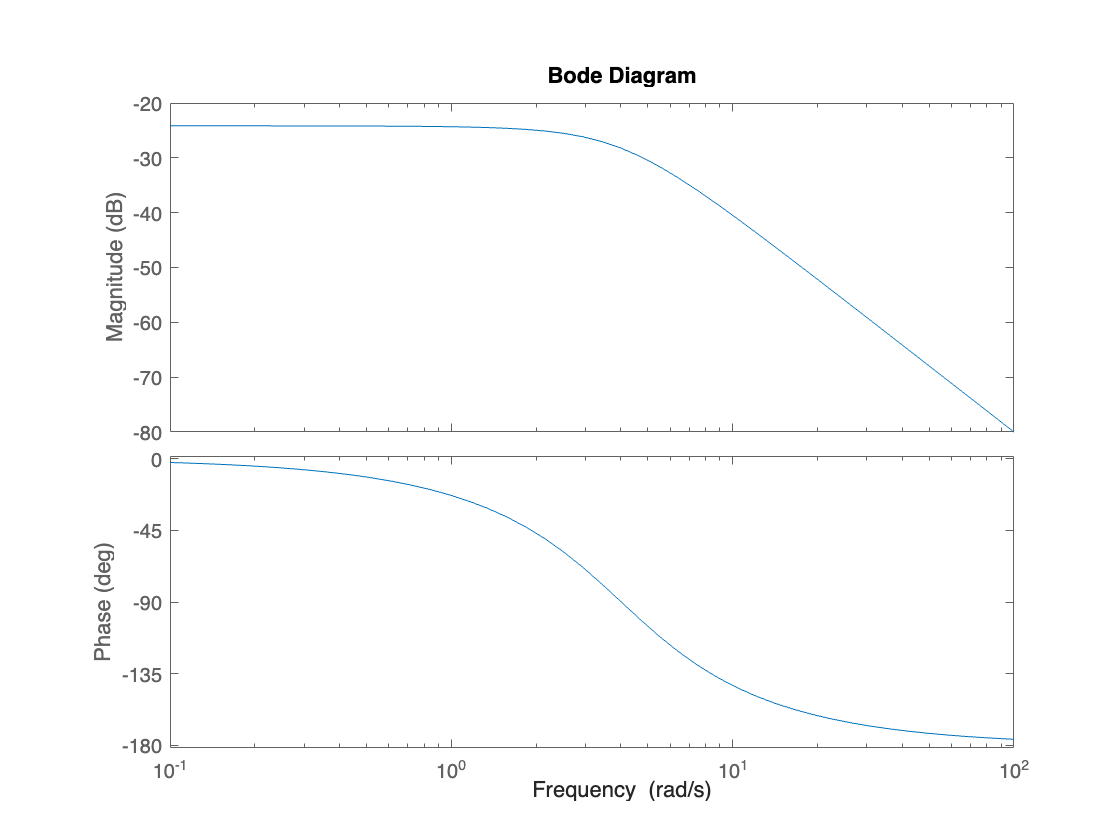

sys_ack = ss(F-G*K, G, H, 0);
% Bode plot and step plot without scaling gain
bode(sys_ack)

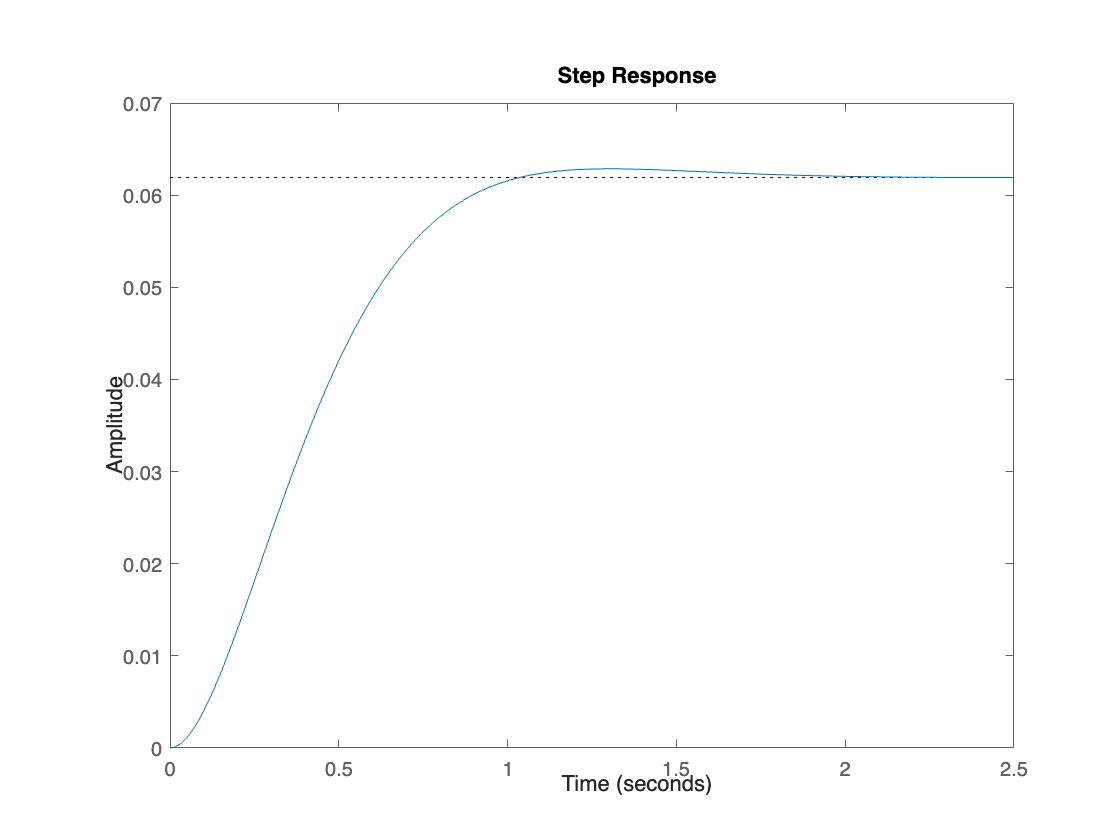


step(sys_ack)

sys_ack

sys_ack =
 
  A = 
           x1      x2
   x1       0       1
   x2  -16.15   -6.43
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
<a href="matlab:disp(char('','                A: [2×2 double] ','                B: [2×1 double] ','                C: [1 0] ','                D: 0 ','                E: [] ','           Scaled: 0 ','        StateName: {2×1 cell} ','        StatePath: {2×1 cell} ','        StateUnit: {2×1 cell} ','    InternalDelay: [0×1 double] ','       InputDelay: 0 ','      OutputDelay: 0 ','        InputName: {''''} ','        InputUnit: {''''} ','       InputGroup: [1×1 struct] ','       OutputName: {''''} ','       OutputUnit: {''''} ','      OutputGroup: [1×1 struct] ','            Notes: [0×1 string] ','         UserData: [] ','             Name: '''' ','               Ts: 0 ','         TimeUnit: ''seconds'' ','     SamplingGrid: [1×1 struct] ',' '))">Model Properties</


[num,den] = ss2tf(sys_ack.A, sys_ack.B, sys_ack.C, sys_ack.D)

num =      0     0     1


den =     1.0000    6.4300   16.1506


% scaling gain
scaling_gain  = 16.1506

scaling_gain = 16.1506

sys_ack = scaling_gain*sys_ack

sys_ack =
 
  A = 
           x1      x2
   x1       0       1
   x2  -16.15   -6.43
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
          x1     x2
   y1  16.15      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


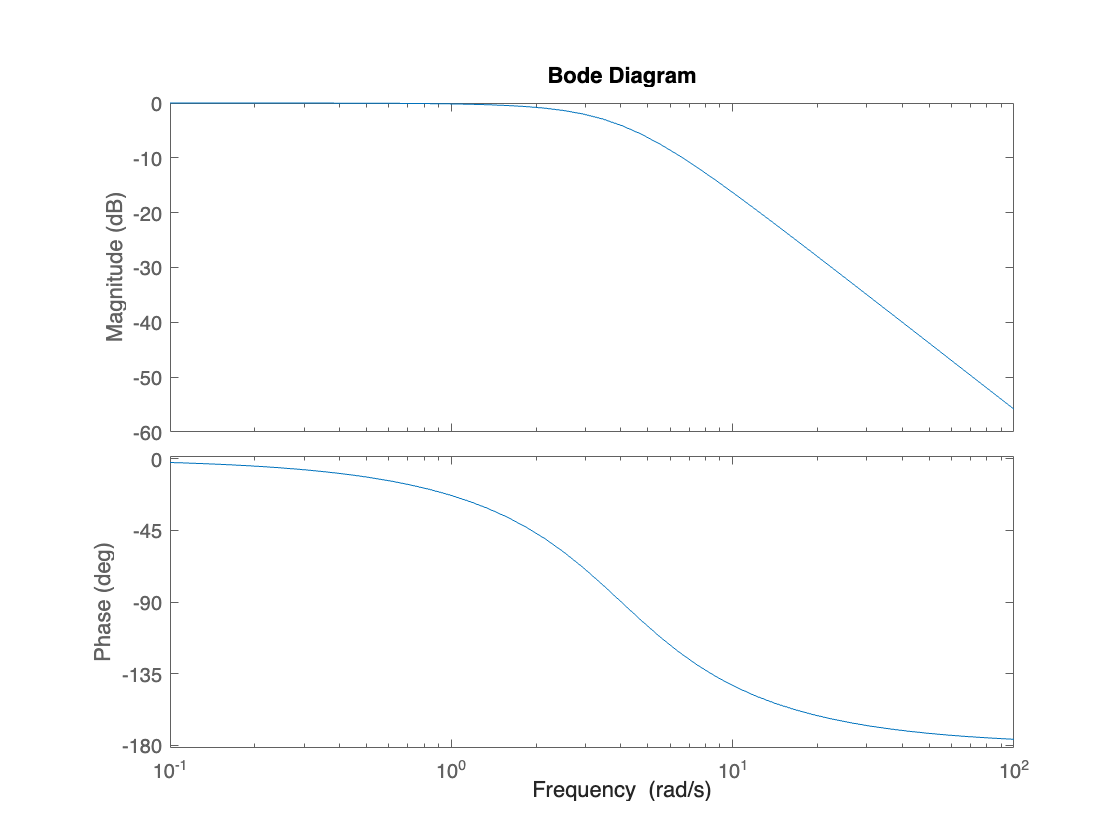

bode(sys_ack)

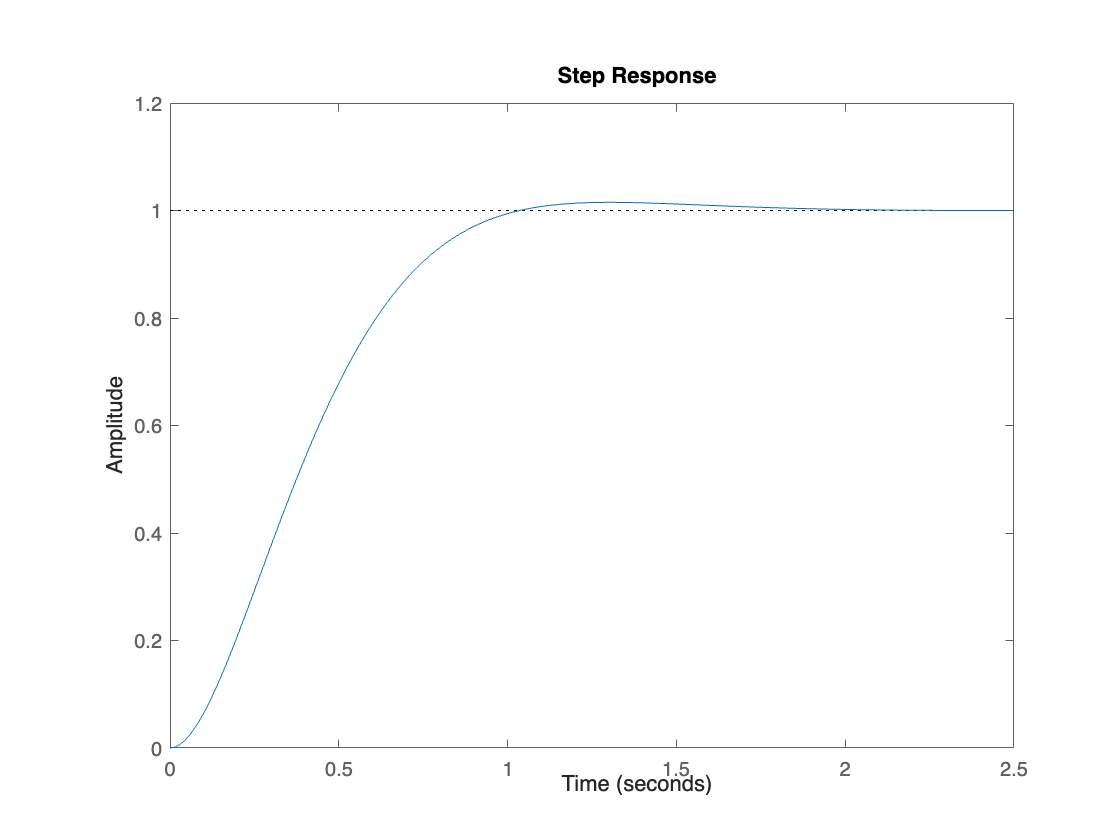

step(sys_ack)

## LQR part

Q = [10, 0; 0, 10];
R = 1;
Tau = [F -G*inv(R)*G'; -Q -F']

Tau =          0    1.0000         0         0
   -1.2000   -3.7100         0   -1.0000
  -10.0000         0         0    1.2000
         0  -10.0000   -1.0000    3.7100


[V, D] = eig(Tau)

V =    -0.0243   -0.0470   -0.0835    0.1289
   -0.1109   -0.0348    0.0619   -0.5882
    0.3022    0.9757   -0.9911    0.4551
    0.9465    0.2114   -0.0836   -0.6560


D =     4.5623         0         0         0
         0    0.7414         0         0
         0         0   -0.7414         0
         0         0         0   -4.5623


v = V(1:2,3:4);
u = V(3:4,3:4);
P = u*inv(v);
K = inv(R)*G'*P

K =     2.1823    1.5937


LQR_K = lqr(F,G, Q,R)

LQR_K =     2.1823    1.5937


sys_lqr = ss(F-G*LQR_K, G, H, 0);
dc_gain = dcgain(sys_lqr)

dc_gain = 0.2957

scaling_gain_lqr = 1/dc_gain

scaling_gain_lqr = 3.3823

sys_lqr = scaling_gain_lqr * sys_lqr

sys_lqr =
 
  A = 
           x1      x2
   x1       0       1
   x2  -3.382  -5.304
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
          x1     x2
   y1  3.382      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
M

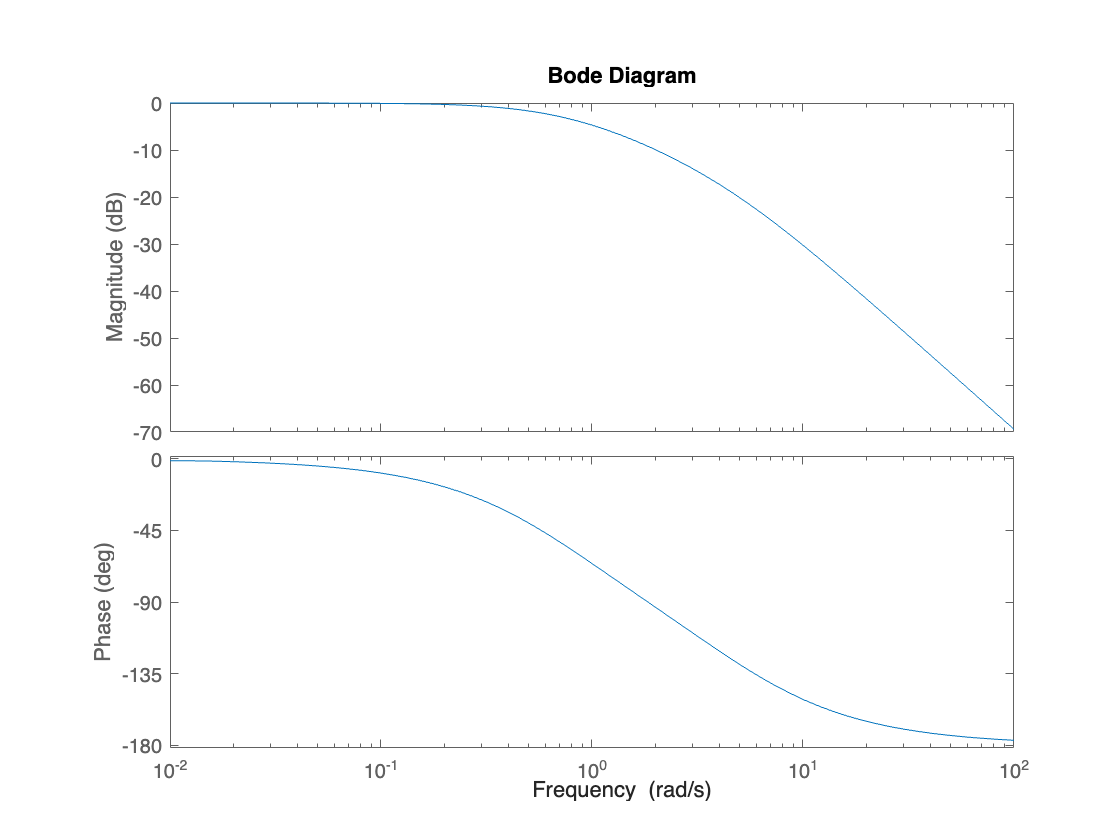

% Bode plot and step plot without scaling gain
bode(sys_lqr)

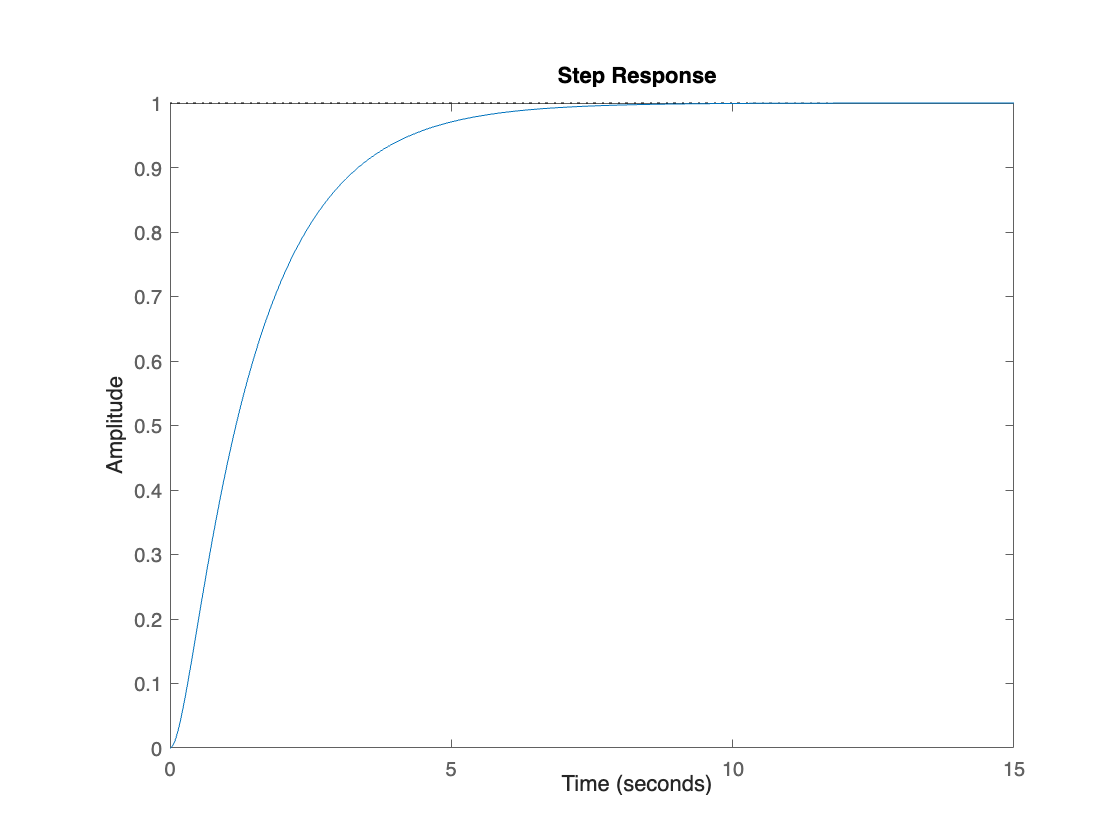

step(sys_lqr)

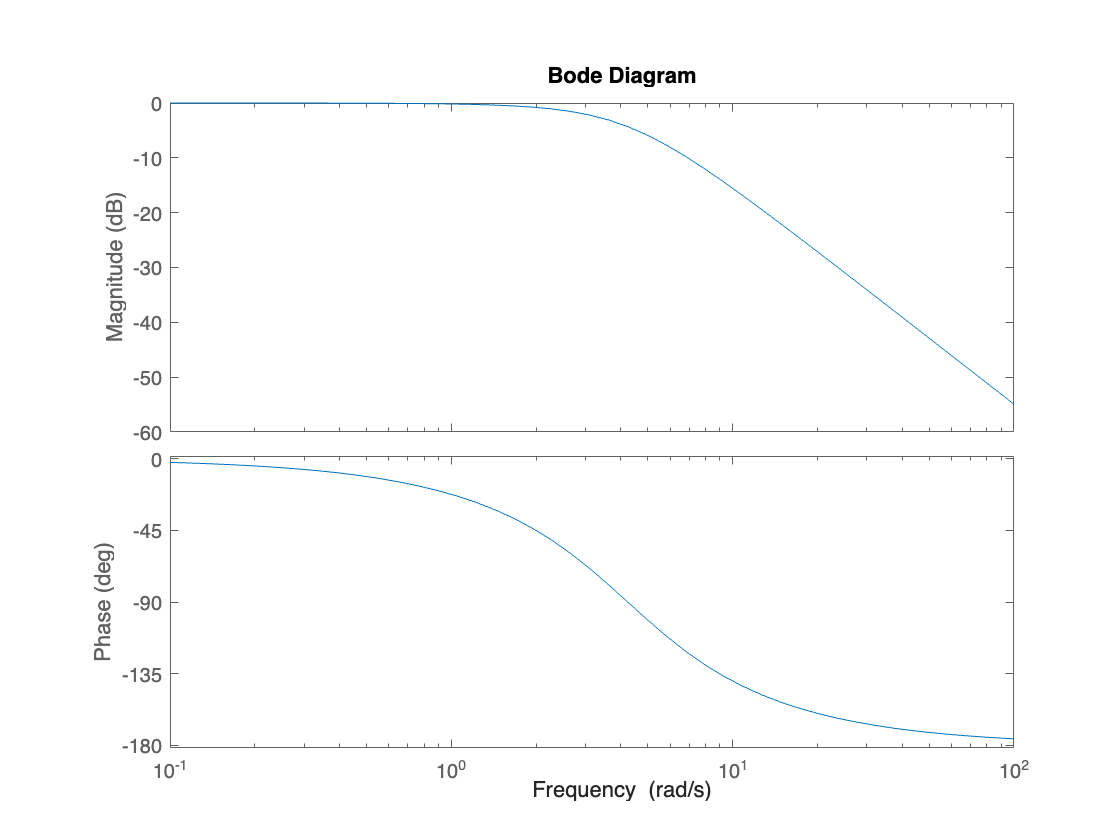

Q2 = [320 0; 0 1]; 
[LQR_K, ~, ~]  = lqr(F, G, Q2, R);
sys_lqr = ss(F-G*LQR_K, G, H, 0);
dc_gain = dcgain(sys_lqr);
scaling_gain_lqr = 1/dc_gain;
sys_lqr = scaling_gain_lqr * sys_lqr;
bode(sys_lqr)